### Исходное ОДУ:


$$\begin{cases}
&y'_1 = f_1 = 2xy_2^{\frac{1}{B}}y_4 \\
&y'_2 = f_2 = 2Bxe^{\frac{B}{C} (y_3 - A)} y_4\\
&y'_3 = f_3 = 2Cxy_4\\
&y'_4 = f_4 = -2xln(y_1)\\
\end{cases}
$$


где параметры`: `$A = -2;\ B = -2;\ C = 2$

A = -2; B = -2; C = 2; c_2=0.15;
F = @(x,y)[ 2*x*y(2)^(1/B)*y(4); 2*B*x*exp(B/C * (y(3)-A))*y(4); 2*C*x*y(4); -2*x*log(y(1))];

### `Точное решение:`


$$\begin{cases}
&y_1(x) = e^{sin(x^2)}    \\
&y_2(x) = e^{Bsin(x^2)} \\
&y_3(x) = C  sin(x^2) + A\\
&y_4(x) = cos(x^2) \\
\end{cases} \\
y_1(0)=y_2(0)=y_4(0)=1; \ y_3(0)=A \\
\textsf{на отрезке } x \in [0,5]$$


y_true1= @(x) exp(sin(x^2));
y_true2= @(x) exp(B*sin(x^2));
y_true3= @(x) C*sin(x^2) + A;
y_true4= @(x) cos(x^2);

y_true = {y_true1,y_true2, y_true3, y_true4};

y_0= [1,1,A,1];
x_0=0; x_1=5;
h=2^(-6);

X = linspace(x_0, x_1, (x_1-x_0)/h);


## Решение 2-х этапным ЯМРК 2-го порядка

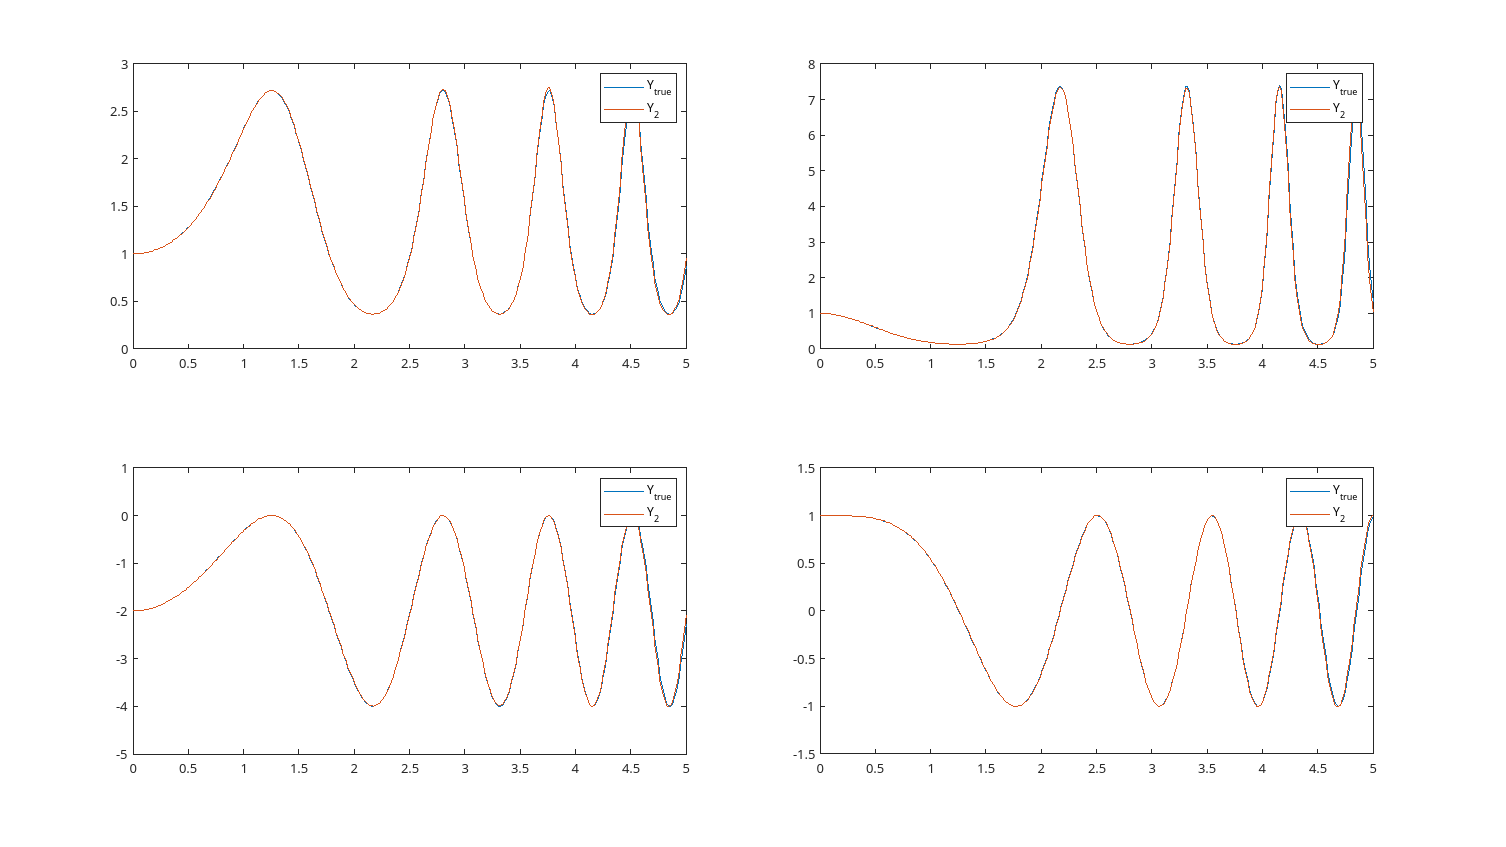


Y_2 = IRKM2_2(F, h,c_2,X,y_0);
Y_true= [arrayfun(y_true1,X); arrayfun(y_true2,X);arrayfun(y_true3,X);arrayfun(y_true4,X)];

figure
set(gcf, 'position', [0 0 1920 1080]);
tiledlayout(2,2);


hold on
nexttile;
p1 = plot(X,Y_true(1,:), X, Y_2(1,:));
legend('Y_{true}', 'Y_2');

nexttile;
p2 = plot(X,Y_true(2,:),X, Y_2(2,:));
legend('Y_{true}', 'Y_2');

nexttile;
p3 = plot(X,Y_true(3,:), X,Y_2(3,:));
legend('Y_{true}', 'Y_2');

nexttile;
p4 = plot(X,Y_true(4,:), X,Y_2(4,:));
legend('Y_{true}', 'Y_2');
hold off

%norm(Y_2(:,end)-Y_true(:,end))

## Решение 3-х этапным ЯМРК 3-го порядка 

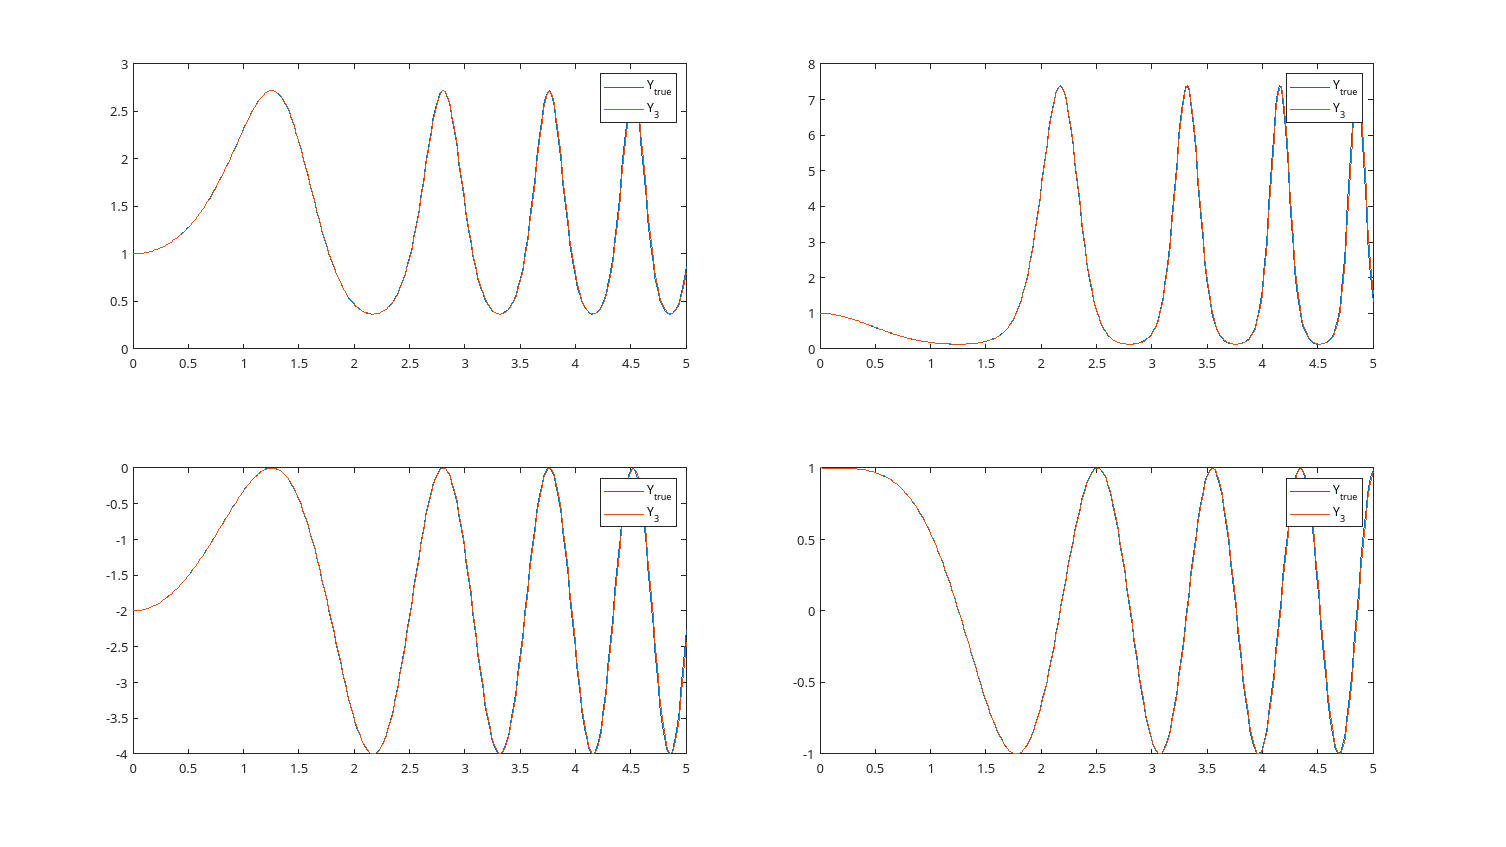

Y_3 = Heun(F,h,X,y_0);

figure
set(gcf, 'position', [0 0 1920 1080]);
tiledlayout(2,2);

hold on
nexttile;
p1 = plot(X,Y_true(1,:), X, Y_3(1,:));
legend('Y_{true}', 'Y_3');

nexttile;
p2 = plot(X,Y_true(2,:),X, Y_3(2,:));
legend('Y_{true}', 'Y_3');

nexttile;
p3 = plot(X,Y_true(3,:), X,Y_3(3,:));
legend('Y_{true}', 'Y_3');

nexttile;
p4 = plot(X,Y_true(4,:), X,Y_3(4,:));
legend('Y_{true}', 'Y_3');
hold off

### Графики зависимости норм точной полной погрешности:

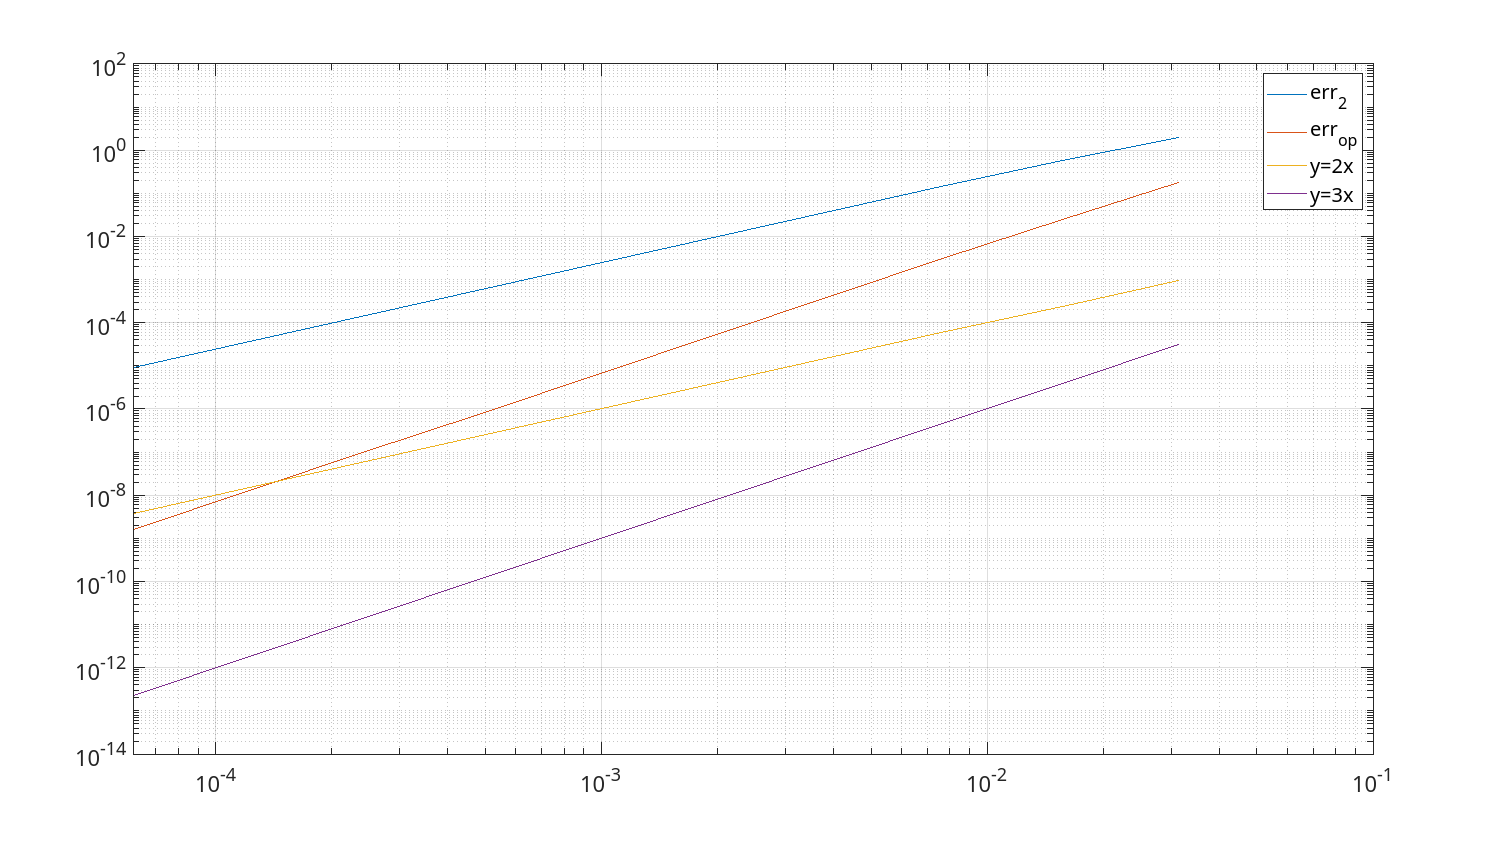

figure
set(gcf, 'position', [0 0 1920 1080]);
format long
hold on
err_2_y = zeros(4,10);
err_3_y = zeros(4,10);
err2_norm = zeros(1,10);
err3_norm = zeros(1,10);
x_vals = zeros(1,10);

for k=5:14
    x_vals(k-4) = 2^(-k);
    X_k = linspace(x_0,x_1,(x_1-x_0)*(2^(k))+1);
    Y_2k = IRKM2_2(F,2^(-k),c_2,X_k,y_0);
    Y_3k = Heun(F,2^(-k),X_k,y_0);

    err_2_y(:,k-4) = Y_2k(:,end)-Y_true(:,end);
    err_3_y(:,k-4) = Y_3k(:,end)-Y_true(:,end);

    err2_norm(k-4) = norm(err_2_y(:,k-4));
    err3_norm(k-4) = norm(err_3_y(:,k-4));
end
t_2 = @(x) x^2;
t_3 = @(x) x^3;

tiledlayout(1,1);
nexttile;

loglog(x_vals, (err2_norm),x_vals,(err3_norm), x_vals, (arrayfun(t_2,x_vals)), x_vals, (arrayfun(t_3,x_vals)) );
grid on
ax = gca;
ax.FontSize = 17;
legend('err_2','err_{op}', 'y=2x','y=3x');

hold off

### Оценка полной погрешности по правилу Рунге

h1 = 2^(-5);
h2 = 2^(-6);
tol = 10^(-5);
p=2;

Xn = linspace(x_0,x_1,(x_1-x_0)/h1);
X2n = linspace(x_0,x_1,(x_1-x_0)/h2);

Y2_n = IRKM2_2(F,h,c_2, Xn,y_0);
Y2_2n = IRKM2_2(F,h,c_2, X2n,y_0);

Y3_n = Heun(F,h,Xn,y_0);
Y3_2n = Heun(F,h,X2n,y_0);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[h2_opt, h3_opt] = optStepRunge(h1, tol, p,Y2_n, Y2_2n, Y3_n, Y3_2n);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

X2_opt = linspace(x_0,x_1,(x_1-x_0)/h2_opt);
X3_opt = linspace(x_0,x_1,(x_1-x_0)/h3_opt);
Y_true_opt2= [arrayfun(y_true1,X2_opt); arrayfun(y_true2,X2_opt);arrayfun(y_true3,X2_opt);arrayfun(y_true4,X2_opt)];
Y_true_opt3= [arrayfun(y_true1,X3_opt); arrayfun(y_true2,X3_opt);arrayfun(y_true3,X3_opt);arrayfun(y_true4,X3_opt)];


Y2_opt = IRKM2_2(F,h2_opt,c_2,X2_opt,y_0);
Y3_opt = Heun(F,h3_opt,X3_opt,y_0);


normArrayTrue2 = zeros(1,length(X2_opt));
normArrayTrue3 = zeros(1,length(X3_opt));
normArray2 = zeros(1,length(X2_opt));
normArray3 = zeros(1,length(X3_opt));

normDiff3 = zeros(1,length(X3_opt));

idx = normArray2;
bigdiff = idx;

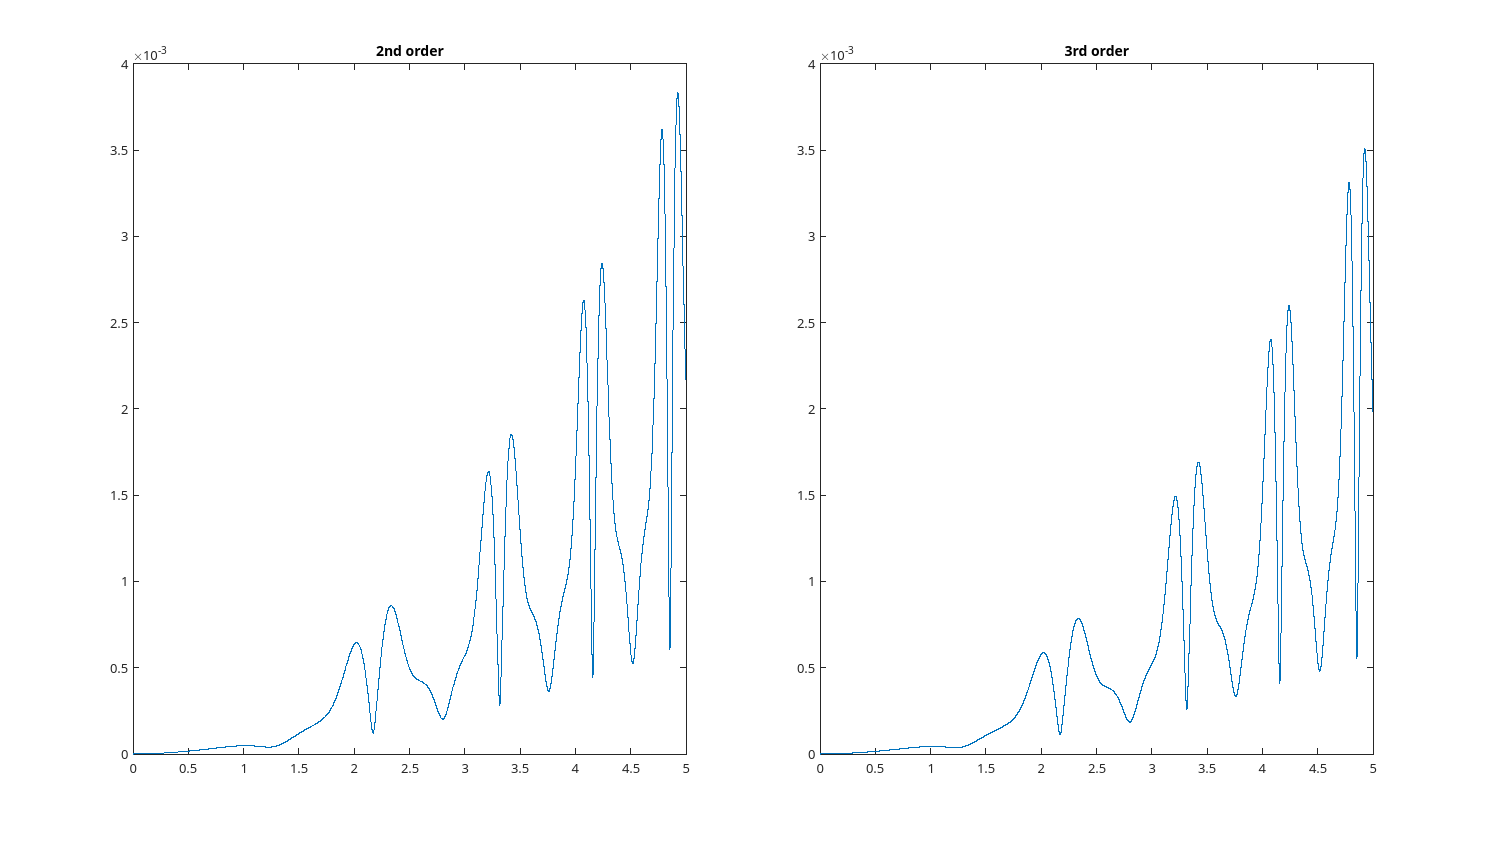

for k = 1:length(X2_opt)
   % normArrayTrue2(k) = norm();
    normArray2(k) = norm(Y_true_opt2(:,k)-Y2_opt(:,k));
end


for k=1:length(X3_opt)
   % normArray3(k) = norm();
    normArray3(k) = norm(Y_true_opt3(:,k)-Y3_opt(:,k));   
end


figure
set(gcf, 'position', [0 0 1920 1080]);
tiledlayout(1,2);

nexttile;
p1 = plot(X2_opt, normArray2);
title(gca, "2nd order")

nexttile;
p2 = plot(X3_opt, normArray3);
title(gca, "3rd order");

## Автовыбор шага

rtol = 1e-6; atol = 1e-12;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[X_auto,Y_auto,H,H_loss] = autoStep(F,x_0,x_1,y_0,c_2,p,rtol,atol);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
H_loss

H_loss =                    0                   0
   0.002500000000000   0.001250000000000


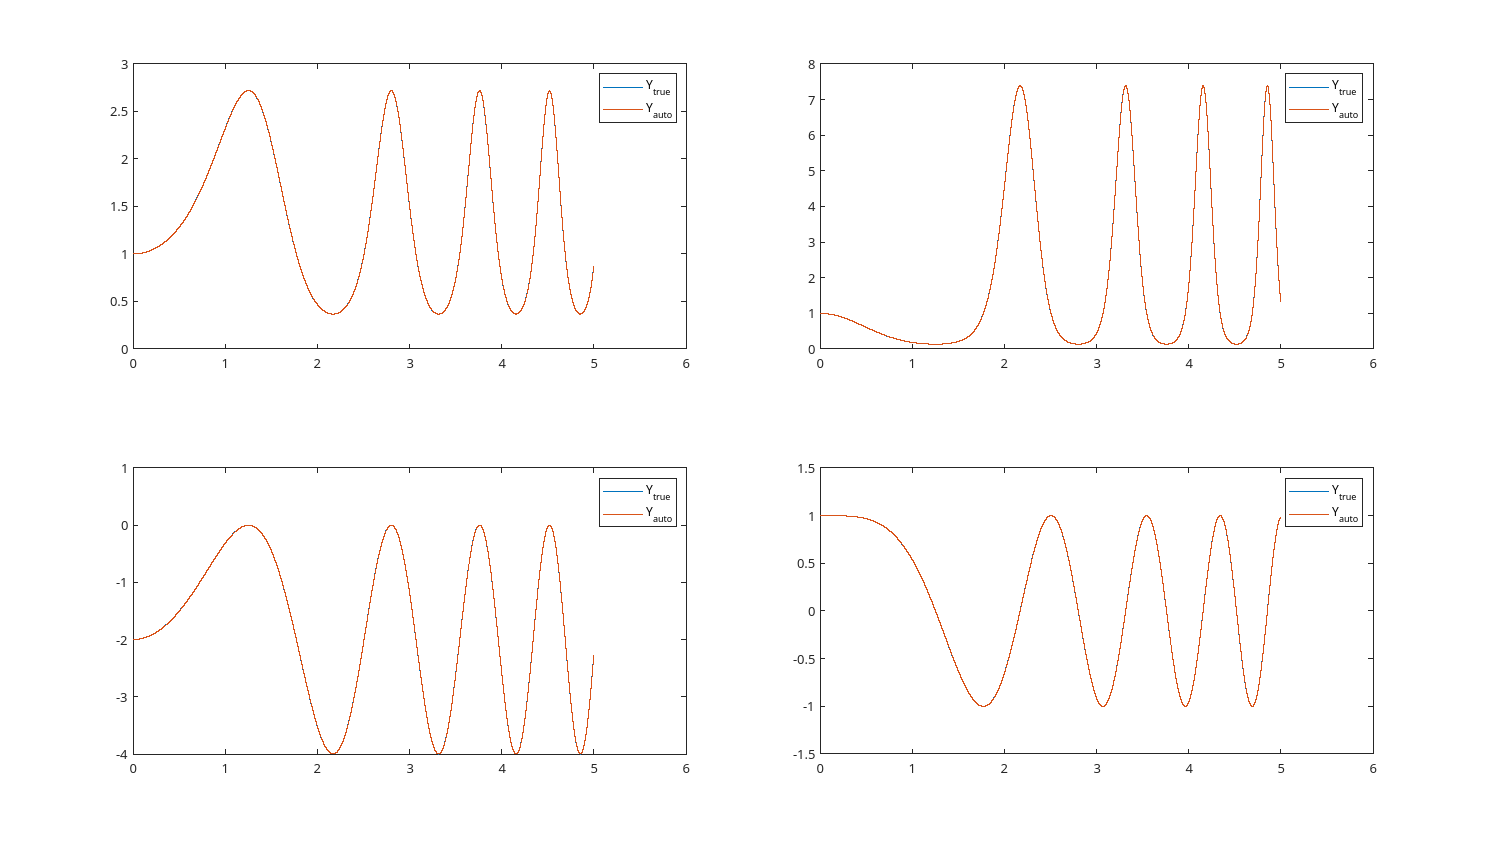


Y_true_auto = [arrayfun(y_true1,X_auto); arrayfun(y_true2,X_auto);arrayfun(y_true3,X_auto);arrayfun(y_true4,X_auto)];

figure
set(gcf, 'position', [0 0 1920 1080]);
tiledlayout(2,2);

hold on
nexttile;
p1 = plot(X_auto,Y_true_auto(1,:), X_auto, Y_auto(1,:));
legend('Y_{true}', 'Y_{auto}');

nexttile;
p2 = plot(X_auto,Y_true_auto(2,:), X_auto, Y_auto(2,:));
legend('Y_{true}', 'Y_{auto}');

nexttile;
p3 = plot(X_auto,Y_true_auto(3,:), X_auto,Y_auto(3,:));
legend('Y_{true}', 'Y_{auto}');

nexttile;
p4 = plot(X_auto,Y_true_auto(4,:), X_auto,Y_auto(4,:));
legend('Y_{true}', 'Y_{auto}');
hold off

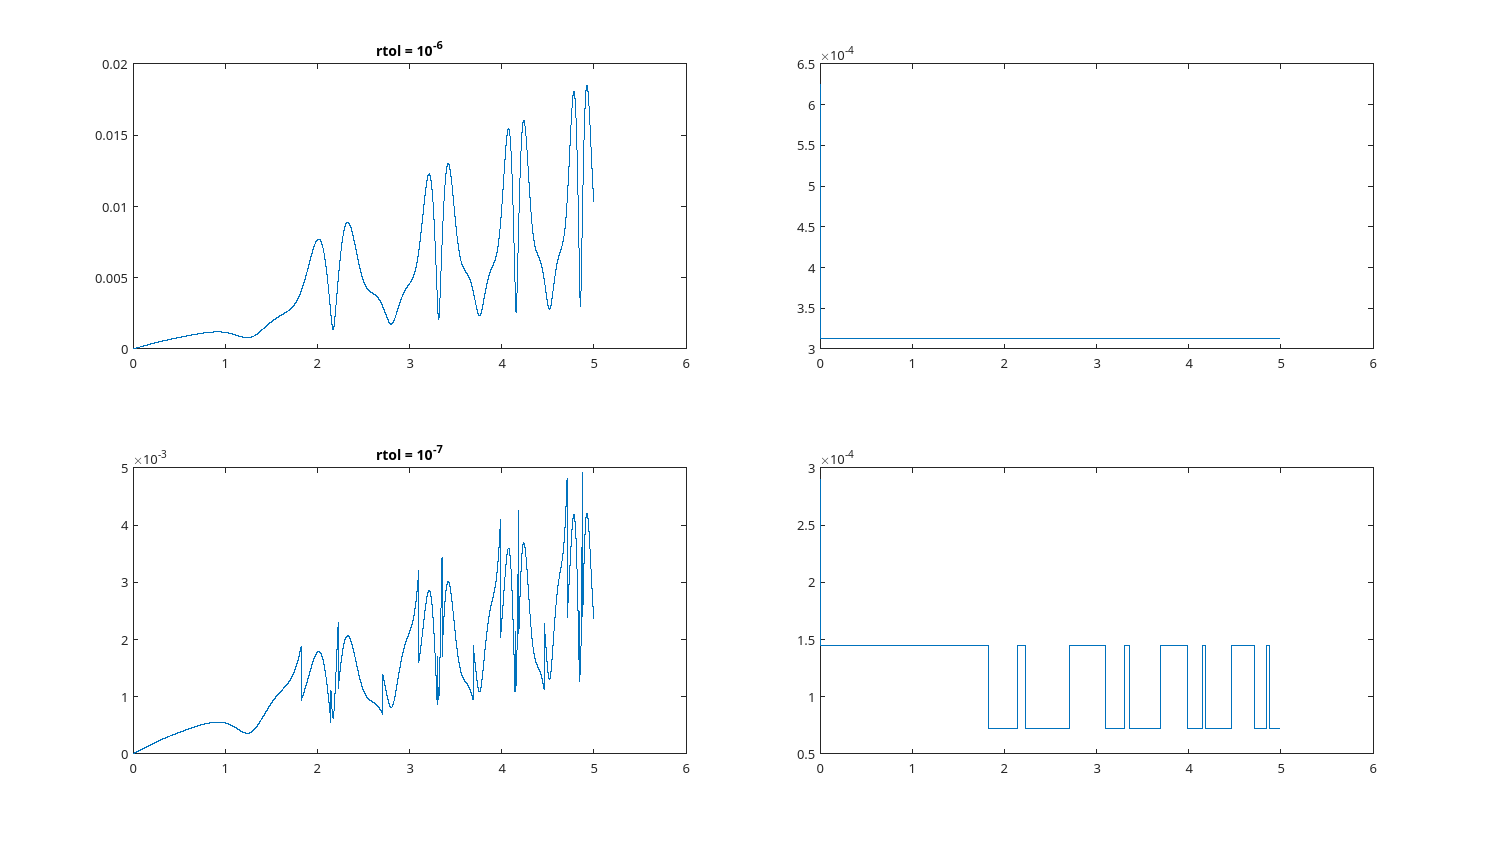


normArrayDiff = zeros(1,length(X_auto));

for k = 1:length(X_auto)
    normArrayDiff(k) = norm(Y_auto(:,k)-Y_true_auto(:,k));
end


figure
set(gcf, 'position', [0 0 1920 1080]);

tiledlayout(2,2);

nexttile;
plot(X_auto, normArrayDiff);
title(gca, "rtol = 10^{-6}")

nexttile;
plot(X_auto,H);


rtol2 = 10^(-7);
[X_auto2,Y_auto2,H2,H_loss2] = autoStep(F,x_0,x_1,y_0,c_2,p,rtol2,atol);
Y_true_auto2 = [arrayfun(y_true1,X_auto2); arrayfun(y_true2,X_auto2);arrayfun(y_true3,X_auto2);arrayfun(y_true4,X_auto2)];
normArrayTrueAuto = zeros(1,length(X_auto2));
normArrayDiff2 = zeros(1,length(X_auto2));

for k = 1:length(X_auto2)
     normArrayDiff2(k) = norm(Y_auto2(:,k)-Y_true_auto2(:,k));
end

nexttile;
plot(X_auto2,  normArrayDiff2);
title(gca, "rtol = 10^{-7}")

nexttile;
plot(X_auto2,H2);


% rtol2 = 10^(-6);
% [X_auto,Y_auto,H,H_loss] = autoStep(F,x_0,x_1,y_0,c_2,p,rtol1,atol);
% normArrayTrueAuto = zeros(1,length(X_auto));
% normArrayAuto = zeros(1,length(X_auto));
% 

% for k = 1:length(X_auto)
%     normArrayTrueAuto(k) = norm(Y_true_auto(:,k));
%     normArrayAuto(k) = norm(Y_auto(:,k));
% end






